% Resources for learning about the data processing pipeline

% GuPPy, a Python toolbox for the analysis of fiber photometry data
% ---Uses a tdt system like we do
% https://www.nature.com/articles/s41598-021-03626-9
%
% pMAT: An Open-Source Software Suite for the Analysis of Fiber Photometry Data
% https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7853640/
% 
% Analyzing and visualizing fiber photometry data with fluoR
% https://bookdown.org/anta8363/fluoR_bookdown/stand.html
%
% 
% Intact-Brain Analyses Reveal Distinct Information Carried by SNc Dopamine Subcircuits
% https://www.sciencedirect.com/science/article/pii/S009286741500851X?via%3Dihub
% 
% Fiber Photometry A 490 nm LED was sinusoidally modulated at 211 Hz and passed through 
% a GFP excitation filter. A 405 nm LED was modulated at 531 Hz and passed through a 405 
% nm bandpass filter. Both light streams were coupled to a high NA (0.48), large core 
% (400 μm) optical fiber patch cord, which was mated to a matching brain implant in each 
% mouse. GCaMP6f fluorescence was collected by the same fiber, passed through a GFP 
% emission filter, and focused onto a photoreceiver. Custom software running on a 
% real-time signal processor controlled the LEDs and independently demodulated the 
% fluorescence brightness due to 405 nm and 490 nm excitation. The timing of behavioral 
% variables was recorded by the same system. To calculate ΔF/F, a least-squares linear 
% fit was applied to the 405 nm signal to align it to the 490 nm signal, producing a 
% fitted 405 nm signal that was used to normalize the 490 nm as follows: 
% ΔF/F = (490 nm signal − fitted 405 nm signal)/fitted 405 nm signal.




clear all
% Environment variables
[root_dir,name,ext] = fileparts(cd);
PROJECT_PATH = fullfile(root_dir, name);
disp(PROJECT_PATH);

/home/benb/Documents/Cui_Lab/Minh_Fiber_Photometry_Analysis



SDKPATH = fullfile(PROJECT_PATH, 'TDTMatlabSDK');
addpath(genpath(SDKPATH));

% Colors for plotting
GCAMP_color = [0.8500, 0.3250, 0.0980];
ISOS_color = [0.4660, 0.6740, 0.1880];
cyan = [0.3010, 0.7450, 0.9330];
gray1 = [.7 .7 .7];
gray2 = [.8 .8 .8];

% data
airpuff = 'airpuff';
chowf = 'chowf';
chowh = 'chowh';
hand = 'hand';
HFDf = 'HFDf';
HFDh = 'HFDh';

EXPERIMENT = airpuff;
SUBJECT = 'J7792';
EXTRA = '_Airpuff-240228-145131';


blockpath = fullfile( ...
    PROJECT_PATH, ...
    'Data', ...
    EXPERIMENT, ...
    strcat(SUBJECT, EXTRA)...
);

% J7792_air-240228-145131
data = TDTbin2mat(blockpath);

Found Synapse note file: /home/benb/Documents/Cui_Lab/Minh_Fiber_Photometry_Analysis/Data/airpuff/J7792_Airpuff-240228-145131/Notes.txt


read from t=0.00s to t=2558.88s


% Setting up chow timestamps
% Timestamp refers to the moment the pellet is removed from the feeder

data.epocs.(EXPERIMENT).onset = data.epocs.Note.onset;

data.epocs.(EXPERIMENT).offSet = data.epocs.(EXPERIMENT).onset + .1;
data.epocs.(EXPERIMENT).name = EXPERIMENT; 

data.epocs.(EXPERIMENT).data = ones(1, length(data.epocs.(EXPERIMENT).onset));

%Stream Names:
GCAMP = 'x465A';
ISOS = 'x405A';
REF_CHANNEL = EXPERIMENT;

%Time ranges for later analysis
time_range = [-10, 20]; % [time before epoch onset, duration of window]
bl_window = [-10, 5]; % [time before epoch onset, durration of window]


FS = data.streams.(GCAMP).fs;
StartBuffer = 2000;
EndBuffer = 2000;
Ts=((1:numel(data.streams.(GCAMP).data(1,:))) /FS);
TS = Ts(StartBuffer:(length(data.streams.(GCAMP).data) - EndBuffer));
Pre = 10;
Post = 10;
EventTS = data.epocs.(EXPERIMENT).onset;
CH_GCAMP = data.streams.(GCAMP).data;
CH_ISOS = data.streams.(ISOS).data;
BL_Width = 5;
BL_Start = 5;
bin = 100;



%% Set Up BaseLine Window Length
BaselineWind=round(BL_Start*FS); 
BaselineWind2=round(BL_Width*FS); 

%% %% %% %% %% %% %% 

 
 % ADD DEFAULT BIN!~
 %% Create Window Size and eliminate events that overlap within a given window
            PreWind=round(Pre*FS);
            PostWind=round(Post*FS);
            
 % Eliminate events with overlapping windows.
 %NEED TO REMOVE -1 IF POSSIBLE!!!

    tmp=[];CurrEvent=EventTS(1);
    %REMOVE -1 HERE
    for i=1:length(EventTS)-1
        if EventTS(i+1)-CurrEvent>Pre+Post
            tmp(end+1,1)=CurrEvent;
            CurrEvent=EventTS(i+1);
        else
        end
    end

    tmp(end+1,1)=EventTS(length(EventTS),1);
    EventTS=tmp;

    %Find Time=0 for the event within the photometry data
    CSidx=[];
    %Ts=Ts'; %FIX FOR WRONG ARRAY ORIENTATION-REMOVED AND FIXED BELOW
    for i=1:length(EventTS)
        [MinVal, CSidx(i,1)]=min(abs(TS(:,:)-EventTS(i)));
    end

%% Obtain the DeltaF/F for each event window
    CS_ISOS=[];CSTS=[];CS_GCAMP=[] ;
    CH_GCAMP=CH_GCAMP';
    CH_ISOS=CH_ISOS';
    counter=1;
    for i=1:length(CSidx)
        %%NEED TO CHECK IF INDEX IS <0 or GREATER THAN LENGTH OF DELTA490, NOT
        %%IF THE VALUE IS LESS THAN 0 OR GREATER THAN THE MAX VALUE OF DELTA490
        if CSidx(i)-(BaselineWind+BaselineWind2)<=0 || CSidx(i)+PostWind > length(Ts)
        else
            %Obtain data within baseline and event window for 405
            %and 490 channels.
            CSTS=(-PreWind:PostWind)./FS;
            CSBL(1,:)=CH_GCAMP((CSidx(i)-(BaselineWind+BaselineWind2)):(CSidx(i)-(BaselineWind))); 
            CSBL2(1,:)=CH_ISOS((CSidx(i)-(BaselineWind+BaselineWind2)):(CSidx(i)-(BaselineWind)));
           
            if i>length(CSidx)
             break
            elseif i<=length(CSidx) 
            CS_ISOS(1,:)=CH_ISOS((CSidx(i)-PreWind):(CSidx(i)+PostWind)); 
            CS_GCAMP(1,:)=CH_GCAMP((CSidx(i)-PreWind):(CSidx(i)+PostWind)); 
            end

            %Smooth to eliminate high frequency noise.
            F_GCAMP=smooth(CS_GCAMP,0.002,'lowess');  %Was 0.002- DJB
            F_ISOS=smooth(CS_ISOS,0.002,'lowess');
            F_GCAMPCSBL=smooth(CSBL,0.002,'lowess');  %Was 0.002- DJB
            F_ISOSCSBL=smooth(CSBL2,0.002,'lowess');


            %Scale and fit data
            bls=polyfit(F_ISOS(1:end),F_GCAMP(1:end),1);
            blsbase=polyfit(F_ISOSCSBL(1:end),F_GCAMPCSBL(1:end),1);
            Y_Fit=bls(1).*F_ISOS+bls(2);
            Y_Fit_base=blsbase(1).*F_ISOSCSBL+blsbase(2);

            %Center data and generate Delta F/F (DF_F) by dividing
            %event window by median of baseline window.
            DF_Event(:,i)=(F_GCAMP(:,1)-Y_Fit(:,1));
            DF_F(:,i)=DF_Event(:,i)./(Y_Fit); %Delta F/F
            DF_F(:,i)=DF_F(:,i)-DF_F(1,i);
            
            DF_Event(:,i)=(F_GCAMP(:,1)-Y_Fit(:,1));
            DF_Event(:,i)=DF_Event(:,i)-DF_Event(1,i); %zero first point
            DF_Base(:,i)=(F_GCAMPCSBL(:,1)-Y_Fit_base(:,1));
            DF_Base(:,i)=DF_Base(:,i)-DF_Base(1,i); %zero to first point
            DF_ZScore(:,counter)=(DF_Event(:,i)-median(DF_Base(:,i)))./mad(DF_Base(:,i)); %Z-Score
            counter=counter+1;
            
            %%Plot Function to compare Robust Z-Score to DF/F            
            % figure; plot(DF_F(:,i)*100);
            % hold on; plot(DF_ZScore(:,i));
            % pause
            % close all
            %%% Clearing variables to reset for the next trial        
            clear CS_ISOS CS_GCAMP F_GCAMP F_ISOS bls Y_Fit

        end
    end

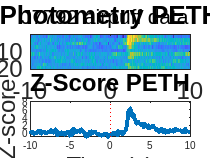

%% %%%%%%%%%%%%%%%PLOTTING & BINNING OF ALL DATA%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%     Z-SCORE     %%%%%%%%%%%%%%%%%%%%%%%%%%%%
DF_ZScore=DF_ZScore';
tmp=[];tmp2=[];
for i=1:bin:length(CSTS)
    if i+bin>length(CSTS)
    tmp(1,end+1)=median(CSTS(i:end));
    tmp2(:,end+1)=median(DF_ZScore(:,i:end),2);
    else
    tmp(1,end+1)=median(CSTS(i:i+bin));
    tmp2(:,end+1)=median(DF_ZScore(:,i:i+bin),2);
    end
end
tsGCAMP=tmp;
DF_ZScore=tmp2;
zStdError = std(DF_ZScore)/sqrt(size(DF_ZScore,1));


figure;
sgtitle(sprintf('%s %s data', SUBJECT, EXPERIMENT), 'fontsize', 16);
h=subplot(2,1,1);
imagesc(tsGCAMP,[1:size(DF_ZScore,1)],(DF_ZScore)); 
% colorbar('SouthOutside');
ylabel('Trial #','fontsize', 18)
% set(h,'XTick',[])
title('Photometry PETH','fontsize', 18)
xlim([-Pre Post])
set(gca,'fontsize',18);
%colormap('jet')
zGCAMP_Mean=(mean(DF_ZScore,1));
zGCAMP_max=max(max(zGCAMP_Mean));
zGCAMP_min=min(min(zGCAMP_Mean));
if zGCAMP_max<0
    zGCAMP_max=0.1;
end


subplot(2,1,2), 
plot(tsGCAMP,zGCAMP_Mean,'LineWidth',3)
title('Z-Score PETH', 'Fontsize', 18);
xlim([-Pre Post])
xlabel('Time (s)', 'FontSize',18)
ylabel('Z-score','fontsize', 18);
ylim([zGCAMP_min zGCAMP_max*1.25]);
hold on
plot([0,0],[zGCAMP_min,zGCAMP_max*1.25],':r')

## Exporting data to a csv

output_table = table(tsGCAMP', zGCAMP_Mean', zStdError', 'VariableNames', {'Time', 'Z Score', 'Std Dev'});
output_file_name = strcat(SUBJECT, '_', EXPERIMENT, '.csv');
output_file_path = fullfile( ...
    PROJECT_PATH, ...
    'output_data', ...
    EXPERIMENT ...
);
mkdir(output_file_path);

writetable(output_table, fullfile(output_file_path, output_file_name));